- Run preprocess_data.m first, this will take raw trajectory data, filter it, store secondary measures, such as speed, turn rates, times, etc. into separate files, all in the subject's folder for later analysis

- Run plot_traj.m next. This will plot the data for visual analysis

- Run this file next

% time to find
% hyp: time to find will depend on prior knowledge. 
timeArray = csvread('stats data/TimeToFind.csv');

timeArray(:,1)=timeArray(:,1)/2.27; % scaling to compensate for length and obstacles
t_time = array2table(timeArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
time_bp=boxplot(table2array(t_time(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Time to find the target (s)')
% -- define the measurements within the subjects (will  be used for all, for right now)
within=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_time=fitrm(t_time,'C1-C4~1', 'WithinDesign', within);
stats_time = ranova(rm_time)

stats_time = 2×8 table
                          SumSq       DF    MeanSq      F         pValue       pValueGG      pValueHF      pValueLB 
                        __________    __    ______    ______    __________    __________    __________    __________

    (Intercept):cond         60269     3     20090    13.973    1.7975e-07    8.7285e-07    2.5353e-07    0.00084422
    Error(cond)         1.2077e+05    84    1437.7                                                                  


if stats_time.pValue(1) < 0.05
    res_time=multcompare(rm_time, 'cond', 'ComparisonType','bonferroni')
    sigstar([],res_time,1);
end

res_time = 12×7 table
    cond_1    cond_2    Difference    StdErr      pValue       Lower      Upper  
    ______    ______    __________    ______    __________    _______    ________

      1         2         22.748       7.257      0.024091      2.146       43.35
      1         3        -7.8269      10.481             1    -37.581      21.927
      1         4         50.781      9.9315    0.00012215     22.586      78.976
      2         1        -22.748       7.257      0.024091     -43.35      -2.146
      2         3        -30.575      10.728      0.048659     -61.03    -0.12031
      2         4         28.032      9.1432      0.028613     2.0755       53.99
      3         1         7.8269      10.481             1    -21.927      37.581
 

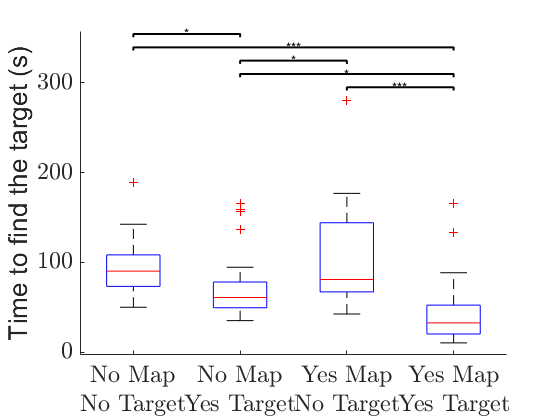

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


%keyboard
% speed
% hyp: speed will depend on prior knowledge.
% higher speeds when target is known (c2 with c1, c4 with c3)
% higher speeds when map is known (c3 with c1)
EKFSpdData = csvread('stats data/RobotSpeedData.csv');
t_EKFSpd = array2table(EKFSpdData,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
EKFSpd_bp = boxplot(table2array(t_EKFSpd(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Robot speed (m/s)')
rm_EKFSpd=fitrm(t_EKFSpd,'C1-C4~1', 'WithinDesign', within);
stats_EKFSpd = ranova(rm_EKFSpd)

stats_EKFSpd = 2×8 table
                         SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                        ________    __    __________    ______    __________    __________    __________    __________

    (Intercept):cond    0.041946     3      0.013982    14.603    9.7521e-08    4.0008e-07    1.0309e-07    0.00067701
    Error(cond)          0.08043    84    0.00095749                                                                  


if stats_EKFSpd.pValue(1) < 0.05
    res_EKFSpd=multcompare(rm_EKFSpd, 'cond', 'ComparisonType','bonferroni')
    sigstar([],res_EKFSpd,1);
end

res_EKFSpd = 12×7 table
    cond_1    cond_2    Difference     StdErr        pValue        Lower         Upper   
    ______    ______    __________    _________    __________    __________    __________

      1         2       -0.024495     0.0070427      0.010012     -0.044489    -0.0045017
      1         3        -0.01365     0.0064165       0.25401     -0.031866     0.0045658
      1         4       -0.051789     0.0084563    7.8637e-06     -0.075796     -0.027782
      2         1        0.024495     0.0070427      0.010012     0.0045017      0.044489
      2         3        0.010845     0.0081706             1     -0.012351      0.034041
      2         4       -0.027294     0.0092443      0.037892     -0.053538      -0.00105
      3         1

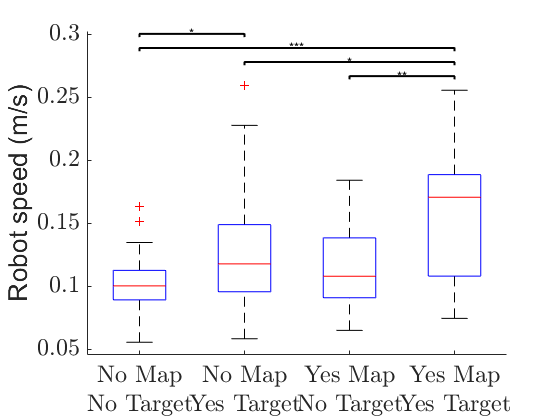

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};



% turn rate
% hyp: turn rate will depend on prior knowledge. 
% Higher turn rate when target is not known
% no difference when map is known
EKFOmegaArray = csvread('stats data/RobotTurnrateData.csv');
t_EKFOmega = array2table(EKFOmegaArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
EKFOmega_bp = boxplot(table2array(t_EKFOmega(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Robot turn rate (rad/s)')
rm_EKFOmega=fitrm(t_EKFOmega,'C1-C4~1', 'WithinDesign', within);
stats_EKFOmega = ranova(rm_EKFOmega)

stats_EKFOmega = 2×8 table
                         SumSq     DF     MeanSq       F        pValue      pValueGG     pValueHF     pValueLB
                        _______    __    ________    ______    _________    _________    _________    ________

    (Intercept):cond    0.30706     3     0.10235    5.3124    0.0021134    0.0036522    0.0025338     0.0288 
    Error(cond)          1.6184    84    0.019267                                                             


if stats_EKFOmega.pValue(1) < 0.05
    res_EKFOmega=multcompare(rm_EKFOmega, 'cond', 'ComparisonType','bonferroni')
    sigstar([],res_EKFOmega,1);
end

res_EKFOmega = 12×7 table
    cond_1    cond_2    Difference     StdErr      pValue       Lower         Upper   
    ______    ______    __________    ________    ________    __________    __________

      1         2        0.031193     0.039718           1     -0.081564       0.14395
      1         3       -0.072768     0.027124    0.072679      -0.14977     0.0042357
      1         4       -0.094656     0.032894    0.045514      -0.18804    -0.0012732
      2         1       -0.031193     0.039718           1      -0.14395      0.081564
      2         3        -0.10396     0.041126     0.10439      -0.22072      0.012793
      2         4        -0.12585     0.037268    0.013007      -0.23165     -0.020049
      3         1        0.072768     0

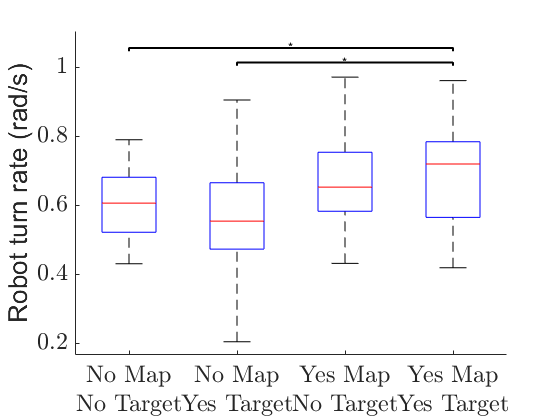

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


% commanded speed
% hyp: commanded speed will depend on prior knowledge. 
% higher speeds when target is known (c2 with c1, c4 with c3)
% higher speeds when map is known (c3 with c1)
comSpeedArray = csvread('stats data/ComSpeedData.csv');
t_comSpeed = array2table(comSpeedArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
comSpeed_bp = boxplot(table2array(t_comSpeed(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Commanded speed (m/s)')
rm_comSpeed=fitrm(t_comSpeed,'C1-C4~1', 'WithinDesign', within);
stats_comSpeed = ranova(rm_comSpeed)

stats_comSpeed = 2×8 table
                         SumSq     DF      MeanSq        F         pValue       pValueGG      pValueHF     pValueLB 
                        _______    __    __________    ______    __________    __________    __________    _________

    (Intercept):cond    0.02796     3       0.00932    11.279    2.7221e-06    1.8052e-05    7.8956e-06    0.0022733
    Error(cond)         0.06941    84    0.00082631                                                                 


if stats_comSpeed.pValue(1) < 0.05
    res_comSpeed=multcompare(rm_comSpeed, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_comSpeed, 1);
end

res_comSpeed = 12×7 table
    cond_1    cond_2    Difference     StdErr        pValue        Lower         Upper   
    ______    ______    __________    _________    __________    __________    __________

      1         2       -0.028955     0.0064117    0.00062418     -0.047157     -0.010753
      1         3       -0.013277     0.0054914       0.13423     -0.028867     0.0023125
      1         4       -0.041009     0.0083114    0.00019927     -0.064605     -0.017414
      2         1        0.028955     0.0064117    0.00062418      0.010753      0.047157
      2         3        0.015678      0.007368       0.25377    -0.0052397      0.036595
      2         4       -0.012054      0.009409             1     -0.038766      0.014658
      3        

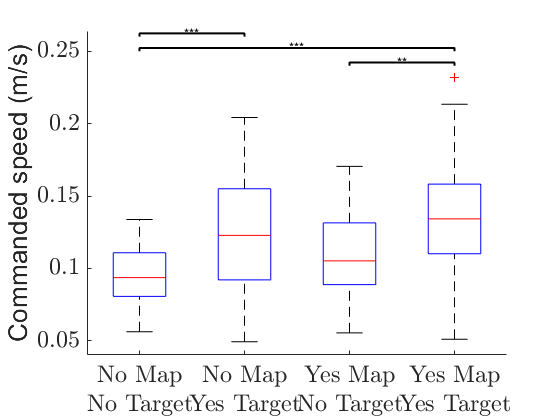

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};



% commanded turn rate
% hyp: commanded turn rate will depend on prior knowledge. 
% Higher turn rate when target is not known
% no difference when map is known
comTurnRateArray = csvread('stats data/ComTurnrateData.csv');
t_comTurnRate = array2table(comTurnRateArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
comTurnRate_bp = boxplot(table2array(t_comTurnRate(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Commanded turn rate (rad/s)')
rm_comTurnRate=fitrm(t_comTurnRate,'C1-C4~1', 'WithinDesign', within);
stats_comTurnRate = ranova(rm_comTurnRate)

stats_comTurnRate = 2×8 table
                         SumSq      DF     MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                        ________    __    _________    ______    __________    __________    __________    __________

    (Intercept):cond    0.068839     3     0.022946    15.711    3.3894e-08    2.3725e-07    6.1398e-08    0.00046305
    Error(cond)          0.12268    84    0.0014605                                                                  


if stats_comTurnRate.pValue(1) < 0.05
    res_comTurnRate=multcompare(rm_comTurnRate, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_comTurnRate,1)
end

res_comTurnRate = 12×7 table
    cond_1    cond_2    Difference     StdErr        pValue        Lower        Upper  
    ______    ______    __________    _________    __________    _________    _________

      1         2         0.045503    0.0081659    3.4912e-05     0.022321     0.068686
      1         3       -0.0079181     0.010131             1    -0.036678     0.020842
      1         4         0.043326    0.0079038    4.4675e-05     0.020888     0.065764
      2         1        -0.045503    0.0081659    3.4912e-05    -0.068686    -0.022321
      2         3        -0.053422      0.01163    0.00050546    -0.086439    -0.020404
      2         4       -0.0021774     0.010256             1    -0.031293     0.026938
      3         1        0.0

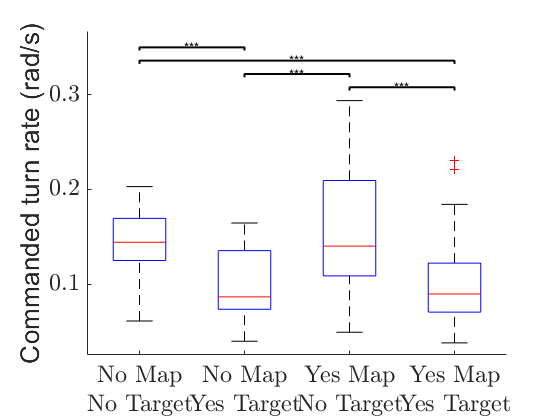

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


% Total distance traveled
TotalDistArray = csvread('stats data/TotalDistanceTravel.csv');
TotalDistArray(:,1)=TotalDistArray(:,1)/2.27;
t_TotalDist = array2table(TotalDistArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
TotalDist_bp = boxplot(table2array(t_TotalDist(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Average total distance traveled (m)')
rm_TotalDist=fitrm(t_TotalDist,'C1-C4~1', 'WithinDesign', within);
stats_TotalDist = ranova(rm_TotalDist)

stats_TotalDist = 2×8 table
                        SumSq     DF    MeanSq      F         pValue      pValueGG     pValueHF     pValueLB
                        ______    __    ______    ______    __________    _________    _________    ________

    (Intercept):cond    362.42     3    120.81    6.2523    0.00069722    0.0029258    0.0021891    0.018532
    Error(cond)         1623.1    84    19.322                                                              


if stats_TotalDist.pValue(1) < 0.05
    res_TotalDist=multcompare(rm_TotalDist, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_TotalDist,1)
end

res_TotalDist = 12×7 table
    cond_1    cond_2    Difference    StdErr      pValue       Lower       Upper  
    ______    ______    __________    _______    ________    _________    ________

      1         2          1.589      0.77387     0.29694     -0.60797       3.786
      1         3        -2.0079       1.1423     0.53831      -5.2509      1.2351
      1         4         2.6886       1.0417    0.092311     -0.26876      5.6459
      2         1         -1.589      0.77387     0.29694       -3.786     0.60797
      2         3        -3.5969        1.299    0.059178      -7.2847    0.090824
      2         4         1.0996      0.95471           1      -1.6108      3.8099
      3         1         2.0079       1.1423     0.53831      -1.2351

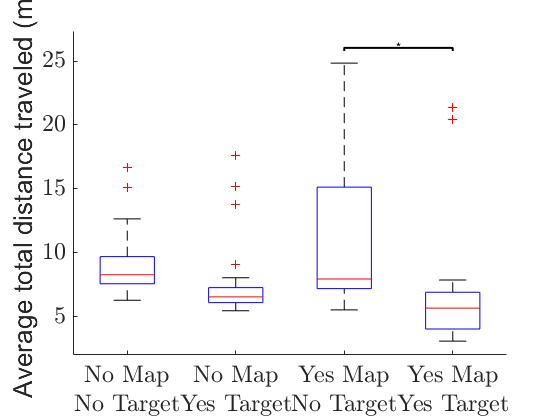

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


% Total time in place traveled
TotalTimeInPlaceArray = csvread('stats data/TotalTimeInPlace.csv');
TotalTimeInPlaceArray(:,1)=TotalTimeInPlaceArray(:,1)/2.27;
t_TotalTimeInPlace = array2table(TotalTimeInPlaceArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
TotalDist_bp = boxplot(table2array(t_TotalTimeInPlace(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Fraction time spent turning in place')
rm_TotalTimeInPlace=fitrm(t_TotalTimeInPlace,'C1-C4~1', 'WithinDesign', within);
stats_TotalTimeInPlace = ranova(rm_TotalTimeInPlace)

stats_TotalTimeInPlace = 2×8 table
                         SumSq     DF     MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                        _______    __    _________    ______    __________    __________    __________    __________

    (Intercept):cond    0.36504     3      0.12168    24.804    1.3746e-11    5.0758e-08    1.9935e-08    2.9265e-05
    Error(cond)         0.41208    84    0.0049057                                                                  


if stats_TotalTimeInPlace.pValue(1) < 0.05
    res_TotalTimeInPlace=multcompare(rm_TotalTimeInPlace, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_TotalTimeInPlace,1)
end

res_TotalTimeInPlace = 12×7 table
    cond_1    cond_2    Difference     StdErr        pValue        Lower         Upper   
    ______    ______    __________    _________    __________    __________    __________

      1         2        -0.12572      0.012421     4.419e-10      -0.16098     -0.090458
      1         3        -0.14033     0.0092449    2.9103e-14      -0.16657      -0.11408
      1         4       -0.058484      0.022935      0.099186      -0.12359     0.0066268
      2         1         0.12572      0.012421     4.419e-10      0.090458       0.16098
      2         3       -0.014608       0.01564             1      -0.05901      0.029795
      2         4        0.067236      0.023041      0.041237     0.0018229       0.13265
      3

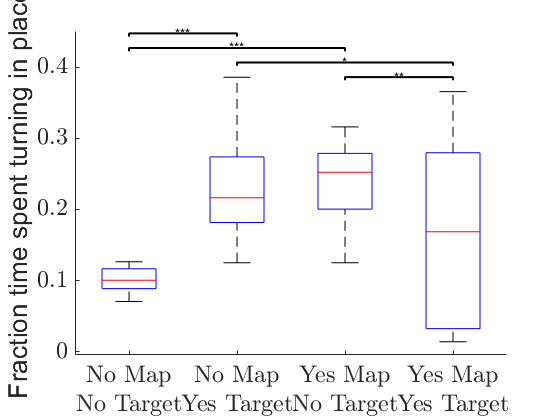

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};



% stopping percentage (bearings)
% hyp: stopping percentage will depend on prior knowledge. 
% higher stopping percentage when map is not known
% Total time in place traveled
TotalTimeStoppingArray = csvread('stats data/TotalTimeStopping.csv');
TotalTimeStoppingArray(:,1) = TotalTimeStoppingArray(:,1)/2.27;
t_TotalTimeStoppingArray = array2table(TotalTimeStoppingArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
TotaltimeStopping_bp = boxplot(table2array(t_TotalTimeStoppingArray(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Average time collecting bearing (s)')
rm_TotalTimeStoppingArray=fitrm(t_TotalTimeStoppingArray,'C1-C4~1', 'WithinDesign', within);
stats_TotalTimeStoppingArray = ranova(rm_TotalTimeStoppingArray)

stats_TotalTimeStoppingArray = 2×8 table
                        SumSq    DF    MeanSq      F         pValue       pValueGG      pValueHF     pValueLB 
                        _____    __    ______    ______    __________    __________    __________    _________

    (Intercept):cond    11548     3    3849.4    10.721    4.8819e-06    1.1876e-05    4.8819e-06    0.0028195
    Error(cond)         30160    84    359.05                                                                 


if stats_TotalTimeStoppingArray.pValue(1) < 0.05
    res_TotalTimeStoppingArray=multcompare(rm_TotalTimeStoppingArray, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_TotalTimeStoppingArray,1)
end

res_TotalTimeStoppingArray = 12×7 table
    cond_1    cond_2    Difference    StdErr      pValue       Lower       Upper 
    ______    ______    __________    ______    __________    ________    _______

      1         2         12.837      3.8064      0.013157      2.0308     23.643
      1         3         2.6473      5.4056             1     -12.699     17.994
      1         4         25.371      5.0032    0.00013702      11.168     39.575
      2         1        -12.837      3.8064      0.013157     -23.643    -2.0308
      2         3         -10.19      5.3255       0.39584     -25.308      4.929
      2         4         12.534       4.703       0.07576    -0.81701     25.886
      3         1        -2.6473      5.4056             1     -1

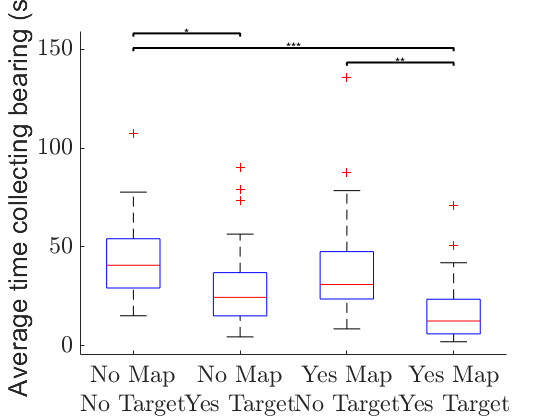

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


TotalPercentStoppingArray = csvread('stats data/TotalPercentStopping.csv');
t_TotalPercentStoppingArray = array2table(TotalPercentStoppingArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
Totalpercentstopping_bp = boxplot(table2array(t_TotalPercentStoppingArray(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Fraction time spent staying still')
rm_TotalPercentStoppingArray=fitrm(t_TotalPercentStoppingArray,'C1-C4~1', 'WithinDesign', within);
stats_TotalPercentStoppingArray = ranova(rm_TotalPercentStoppingArray)

stats_TotalPercentStoppingArray = 2×8 table
                         SumSq     DF     MeanSq       F         pValue      pValueGG      pValueHF      pValueLB 
                        _______    __    ________    ______    __________    _________    __________    __________

    (Intercept):cond    0.91484     3     0.30495    27.988    1.2105e-12    8.495e-10    1.8126e-10    1.2543e-05
    Error(cond)         0.91523    84    0.010896                                                                 


if stats_TotalPercentStoppingArray.pValue(1) < 0.05
    res_TotalPercentStoppingArray=multcompare(rm_TotalPercentStoppingArray, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_TotalPercentStoppingArray,1)
end

res_TotalPercentStoppingArray = 12×7 table
    cond_1    cond_2    Difference     StdErr       pValue        Lower         Upper  
    ______    ______    __________    ________    __________    __________    _________

      1         2        0.028671      0.02019       0.99975     -0.028646     0.085988
      1         3         0.05089     0.019918      0.098034    -0.0056545      0.10744
      1         4         0.22733     0.032911    9.9203e-07        0.1339      0.32077
      2         1       -0.028671      0.02019       0.99975     -0.085988     0.028646
      2         3        0.022219     0.026499             1     -0.053009     0.097447
      2         4         0.19866     0.034195    1.8349e-05       0.10158      0.29574
      3       

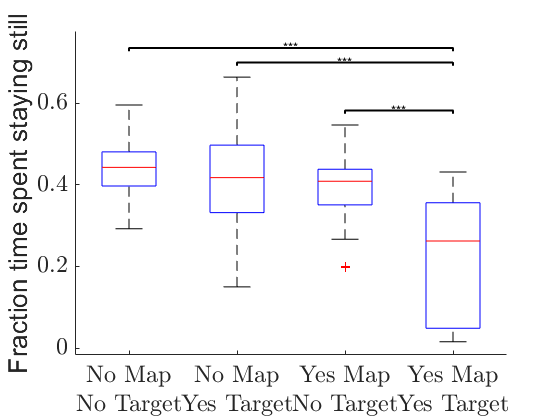

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};



% ------------------------------------------------------------
% -- looking at only conditions 3, 4a, and 4b

% speed between 3, 4a and 4b
% knowledge of the target not present in location 1 implies it's presence in location 2, 
% thus leading to an increase in speed which resembles when target location is known in 4a
EKFSpdData = csvread('stats data/RobotSpeedData.csv');
EKFSpdData = EKFSpdData(EKFSpdData(:,5)~=0,[3,4,5]);
t_EKFSpd = array2table(EKFSpdData,...
    'VariableNames',{'C1','C2','C3'});
EKFSpd_bp = boxplot(table2array(t_EKFSpd(:,1:3)), 'labels', {'C3','C4', 'C5'});
ylabel('Speed prior knowledge accuracy (m/s)')
within3=array2table([1 2 3]', 'variablenames', {'cond'});
rm_EKFSpd=fitrm(t_EKFSpd,'C1-C3~1', 'WithinDesign', within3);
stats_EKFSpd = ranova(rm_EKFSpd)

stats_EKFSpd = 2×8 table
                         SumSq      DF     MeanSq        F       pValue      pValueGG     pValueHF     pValueLB
                        ________    __    _________    _____    _________    _________    _________    ________

    (Intercept):cond    0.016158     2     0.008079    6.689    0.0045326    0.0056226    0.0045326    0.022585
    Error(cond)         0.031403    26    0.0012078                                                            


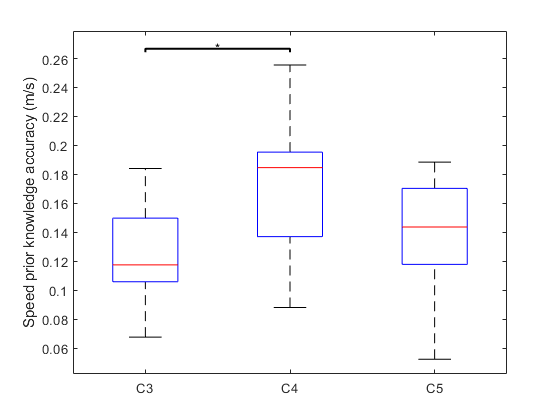

res_EKFSpd = 6×7 table
    cond_1    cond_2    Difference     StdErr      pValue       Lower        Upper   
    ______    ______    __________    ________    ________    _________    __________

      1         2       -0.046733     0.014085    0.016655    -0.085409    -0.0080579
      1         3       -0.013713     0.011229     0.73116    -0.044548      0.017123
      2         1        0.046733     0.014085    0.016655    0.0080579      0.085409
      2         3        0.033021     0.013898     0.10068    -0.005142      0.071184
      3         1        0.013713     0.011229     0.73116    -0.017123      0.044548
      3         2       -0.033021     0.013898     0.10068    -0.071184      0.005142


if stats_EKFSpd.pValue(1) < 0.05
    res_EKFSpd=multcompare(rm_EKFSpd, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_EKFSpd,1)
end

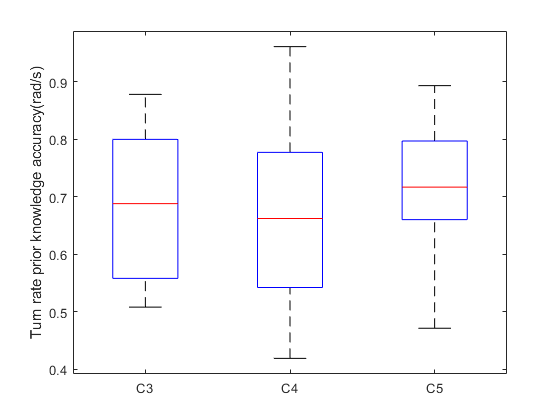


EKFOmegaArray = csvread('stats data/RobotTurnrateData.csv');
EKFOmegaArray = EKFOmegaArray((EKFOmegaArray(:,5) ~= 0), [3,4,5]);
t_EKFOmega = array2table(EKFOmegaArray,...
    'VariableNames',{'C1','C2','C3'});
EKFOmega_bp = boxplot(table2array(t_EKFOmega(:,1:3)), 'labels', {'C3','C4','C5'});
ylabel('Turn rate prior knowledge accuracy(rad/s)')

rm_EKFOmega=fitrm(t_EKFOmega,'C1-C3~1', 'WithinDesign', within3);
stats_EKFOmega = ranova(rm_EKFOmega)

stats_EKFOmega = 2×8 table
                          SumSq      DF     MeanSq         F       pValue     pValueGG    pValueHF    pValueLB
                        _________    __    _________    _______    _______    ________    ________    ________

    (Intercept):cond    0.0080051     2    0.0040026    0.19268    0.82591    0.78723     0.81358      0.6679 
    Error(cond)            0.5401    26     0.020773                                                          


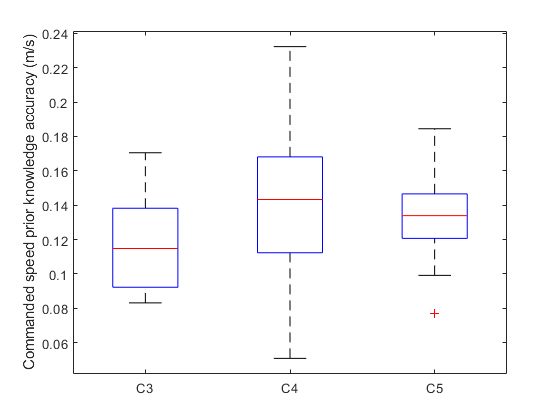

if stats_EKFOmega.pValue(1) < 0.05
    res_EKFOmega=multcompare(rm_EKFOmega, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_EKFOmega,1)
end

% commanded speed
% hyp: commanded speed will depend on prior knowledge. 
% higher speeds when target is known (c2 with c1, c4 with c3)
% higher speeds when map is known (c3 with c1)
comSpeedArray = csvread('stats data/ComSpeedData.csv');
comSpeedArray = comSpeedArray((comSpeedArray(:,5) ~= 0), [3,4,5]);
t_comSpeed = array2table(comSpeedArray,...
    'VariableNames',{'C1','C2','C3'});
comSpeed_bp = boxplot(table2array(t_comSpeed(:,1:3)), 'labels', {'C3','C4','C5'});
ylabel('Commanded speed prior knowledge accuracy (m/s)')

rm_comSpeed=fitrm(t_comSpeed,'C1-C3~1', 'WithinDesign', within3);
stats_comSpeed = ranova(rm_comSpeed)

stats_comSpeed = 2×8 table
                          SumSq      DF      MeanSq        F       pValue     pValueGG    pValueHF    pValueLB
                        _________    __    __________    ______    _______    ________    ________    ________

    (Intercept):cond    0.0043595     2     0.0021798    2.2568    0.12481    0.14069     0.13558     0.15692 
    Error(cond)          0.025112    26    0.00096585                                                         


if stats_comSpeed.pValue(1) < 0.05
    res_comSpeed=multcompare(rm_comSpeed, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_comSpeed, 1);
end


% commanded turn rate
% hyp: commanded turn rate will depend on prior knowledge. 
% Higher turn rate when target is not known
% no difference when map is known
comTurnRateArray = csvread('stats data/ComTurnrateData.csv');
comTurnRateArray = comTurnRateArray((comTurnRateArray(:,5) ~= 0), [3,4,5]);
t_comTurnRate = array2table(comTurnRateArray,...
    'VariableNames',{'C1','C2','C3'});
comTurnRate_bp = boxplot(table2array(t_comTurnRate(:,1:3)), 'labels', {'C3','C4','C5'});
ylabel('Commanded turn rate prior knowledge accuracy (rad/s)')
rm_comTurnRate=fitrm(t_comTurnRate,'C1-C3~1', 'WithinDesign', within3);
stats_comTurnRate = ranova(rm_comTurnRate)

stats_comTurnRate = 2×8 table
                         SumSq      DF     MeanSq        F        pValue      pValueGG    pValueHF     pValueLB
                        ________    __    _________    ______    _________    ________    _________    ________

    (Intercept):cond    0.041686     2     0.020843    5.9712    0.0073459    0.011122    0.0081025    0.029567
    Error(cond)         0.090755    26    0.0034906                                                            


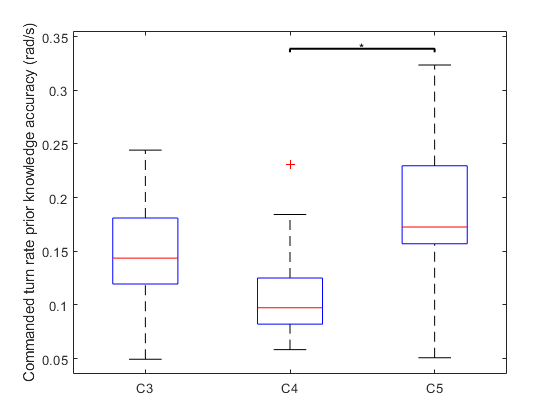

res_comTurnRate = 6×7 table
    cond_1    cond_2    Difference     StdErr      pValue       Lower        Upper   
    ______    ______    __________    ________    ________    _________    __________

      1         2        0.038616     0.019224      0.1974    -0.014171      0.091403
      1         3       -0.038554     0.020499     0.24779    -0.094843      0.017736
      2         1       -0.038616     0.019224      0.1974    -0.091403      0.014171
      2         3       -0.077169     0.026574    0.036946     -0.15014    -0.0041979
      3         1        0.038554     0.020499     0.24779    -0.017736      0.094843
      3         2        0.077169     0.026574    0.036946    0.0041979       0.15014


if stats_comTurnRate.pValue(1) < 0.05
    res_comTurnRate=multcompare(rm_comTurnRate, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_comTurnRate,1)
end




% NASA TLX
% all stats
% -- Questions that were on the NASA TLX with the corresponding value bar range
% -- Q1) Mental demand: Low - High
% -- Q2) Physical demand: Low - High
% -- Q3) Temporal demand: Low - High
% -- Q4) Performance: Perfect - Failure
% -- Q5) Effort: Low - High
% -- Q6) Frustration: Low - High

NASATLXArrayQ1 = csvread('stats data/TLX_question_1.csv');
t_NASATLXQ1 = array2table(NASATLXArrayQ1,...
    'VariableNames',{'C1','C2','C3','C4'});
NASATLXQ1_bp = boxplot(table2array(t_NASATLXQ1), 'labels', {'C1','C2','C3','C4'});
ylabel('Question response for Q1')
within2=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_NASATLXQ1=fitrm(t_NASATLXQ1,'C1-C4~1', 'WithinDesign', within2);
stats_NASATLXQ1 = ranova(rm_NASATLXQ1)

stats_NASATLXQ1 = 2×8 table
                        SumSq     DF    MeanSq      F        pValue      pValueGG    pValueHF     pValueLB
                        ______    __    ______    ______    _________    ________    _________    ________

    (Intercept):cond    2294.8     3    764.94    4.1914    0.0081526    0.010611    0.0081526    0.050116
    Error(cond)          15330    84     182.5                                                            


if stats_NASATLXQ1.pValue(1) < 0.05
    res_NASATLXQ1=multcompare(rm_NASATLXQ1, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_NASATLXQ1,1)
end

res_NASATLXQ1 = 12×7 table
    cond_1    cond_2    Difference    StdErr     pValue      Lower      Upper  
    ______    ______    __________    ______    ________    _______    ________

      1         2         11.379      4.2541    0.074041    -0.6977      23.456
      1         3         9.4828      3.2952    0.045506    0.12777      18.838
      1         4         9.4828      3.6918    0.095001    -0.9981      19.964
      2         1        -11.379      4.2541    0.074041    -23.456      0.6977
      2         3        -1.8966      3.2865           1    -11.227      7.4337
      2         4        -1.8966      3.4688           1    -11.744      7.9513
      3         1        -9.4828      3.2952    0.045506    -18.838    -0.12777
      3       

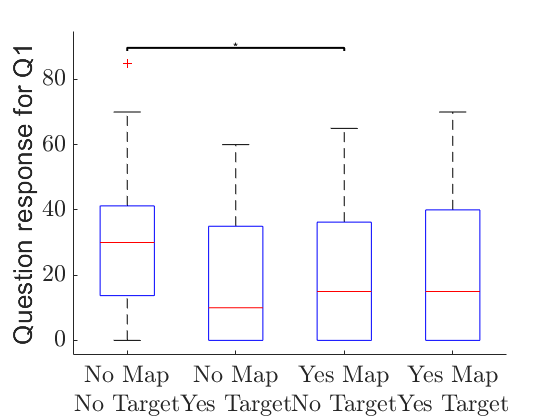

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


NASATLXArrayQ2 = csvread('stats data/TLX_question_2.csv');
t_NASATLXQ2 = array2table(NASATLXArrayQ2,...
    'VariableNames',{'C1','C2','C3','C4'});
NASATLXQ2_bp = boxplot(table2array(t_NASATLXQ2), 'labels', {'C1','C2','C3','C4'});
ylabel('Question response for Q2')
within2=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_NASATLXQ2=fitrm(t_NASATLXQ2,'C1-C4~1', 'WithinDesign', within2);
stats_NASATLXQ2 = ranova(rm_NASATLXQ2)

stats_NASATLXQ2 = 2×8 table
                        SumSq    DF    MeanSq      F        pValue      pValueGG    pValueHF    pValueLB
                        _____    __    ______    ______    _________    ________    ________    ________

    (Intercept):cond     1511     3    503.66    4.1396    0.0086832    0.017823    0.015019    0.05146 
    Error(cond)         10220    84    121.67                                                           


if stats_NASATLXQ2.pValue(1) < 0.05
    res_NASATLXQ2=multcompare(rm_NASATLXQ2, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_NASATLXQ2,1)
end

res_NASATLXQ2 = 12×7 table
    cond_1    cond_2    Difference     StdErr     pValue      Lower       Upper 
    ______    ______    ___________    ______    ________    ________    _______

      1         2            8.7931    3.4887     0.10619      -1.111     18.697
      1         3                 5    2.4313     0.29497     -1.9024     11.902
      1         4            8.7931    3.3993    0.091068    -0.85723     18.443
      2         1           -8.7931    3.4887     0.10619     -18.697      1.111
      2         3           -3.7931    1.9798     0.39385     -9.4137     1.8274
      2         4        1.7764e-15    2.6144           1      -7.422      7.422
      3         1                -5    2.4313     0.29497     -11.902     1.9024
     

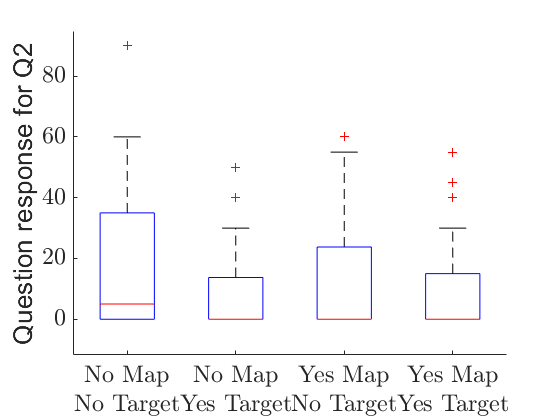

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


NASATLXArrayQ3 = csvread('stats data/TLX_question_3.csv');
t_NASATLXQ3 = array2table(NASATLXArrayQ3,...
    'VariableNames',{'C1','C2','C3','C4'});
NASATLXQ3_bp = boxplot(table2array(t_NASATLXQ3), 'labels', {'C1','C2','C3','C4'});
ylabel('Question response for Q3')
within2=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_NASATLXQ3=fitrm(t_NASATLXQ3,'C1-C4~1', 'WithinDesign', within2);
stats_NASATLXQ3 = ranova(rm_NASATLXQ3)

stats_NASATLXQ3 = 2×8 table
                        SumSq     DF    MeanSq      F       pValue     pValueGG    pValueHF    pValueLB
                        ______    __    ______    ______    _______    ________    ________    ________

    (Intercept):cond    1242.2     3    414.08    1.9262    0.13155     0.1475     0.14219     0.17612 
    Error(cond)          18058    84    214.97                                                         


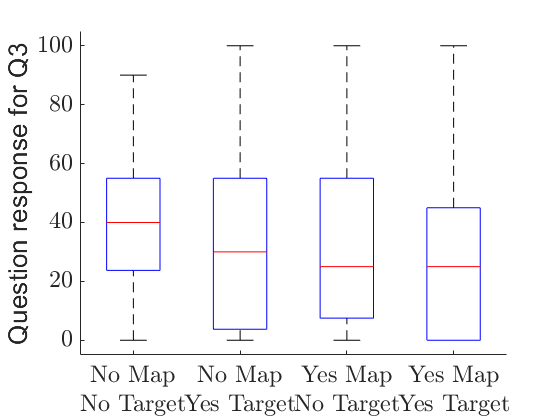

if stats_NASATLXQ3.pValue(1) < 0.05
    res_NASATLXQ3=multcompare(rm_NASATLXQ3, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_NASATLXQ3,1)
end
% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


NASATLXArrayQ4 = csvread('stats data/TLX_question_4.csv');
t_NASATLXQ4 = array2table(NASATLXArrayQ4,...
    'VariableNames',{'C1','C2','C3','C4'});
NASATLXQ4_bp = boxplot(table2array(t_NASATLXQ4), 'labels', {'C1','C2','C3','C4'});
ylabel('Question response for Q4')
within2=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_NASATLXQ4=fitrm(t_NASATLXQ4,'C1-C4~1', 'WithinDesign', within2);
stats_NASATLXQ4 = ranova(rm_NASATLXQ4)

stats_NASATLXQ4 = 2×8 table
                        SumSq     DF    MeanSq       F       pValue     pValueGG    pValueHF    pValueLB
                        ______    __    ______    _______    _______    ________    ________    ________

    (Intercept):cond    255.17     3    85.057    0.87054    0.45977    0.41379     0.41936     0.35878 
    Error(cond)         8207.3    84    97.706                                                          


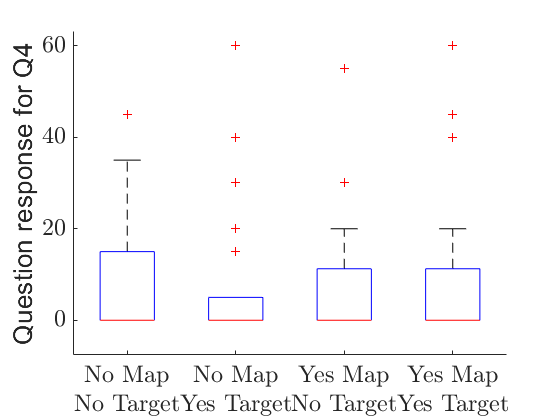

if stats_NASATLXQ4.pValue(1) < 0.05
    res_NASATLXQ4=multcompare(rm_NASATLXQ4, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_NASATLXQ4,1)
end
% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


NASATLXArrayQ5 = csvread('stats data/TLX_question_5.csv');
t_NASATLXQ5 = array2table(NASATLXArrayQ5,...
    'VariableNames',{'C1','C2','C3','C4'});
NASATLXQ5_bp = boxplot(table2array(t_NASATLXQ5), 'labels', {'C1','C2','C3','C4'});
ylabel('Question response for Q5')
within2=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_NASATLXQ5=fitrm(t_NASATLXQ5,'C1-C4~1', 'WithinDesign', within2);
stats_NASATLXQ5 = ranova(rm_NASATLXQ5)

stats_NASATLXQ5 = 2×8 table
                        SumSq     DF    MeanSq      F        pValue      pValueGG     pValueHF     pValueLB
                        ______    __    ______    ______    _________    _________    _________    ________

    (Intercept):cond    4352.4     3    1450.8    5.8579    0.0011074    0.0019466    0.0012592    0.022246
    Error(cond)          20804    84    247.67                                                             


if stats_NASATLXQ5.pValue(1) < 0.05
    res_NASATLXQ5=multcompare(rm_NASATLXQ5, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_NASATLXQ5,1)
end

res_NASATLXQ5 = 12×7 table
    cond_1    cond_2    Difference    StdErr     pValue       Lower      Upper 
    ______    ______    __________    ______    _________    _______    _______

      1         2          14.828     3.8079    0.0033486     4.0172     25.638
      1         3          15.172      3.693    0.0018838     4.6883     25.657
      1         4          9.8276     4.6917      0.27224     -3.492     23.147
      2         1         -14.828     3.8079    0.0033486    -25.638    -4.0172
      2         3         0.34483     3.1771            1    -8.6749     9.3645
      2         4              -5     4.6158            1    -18.104     8.1039
      3         1         -15.172      3.693    0.0018838    -25.657    -4.6883
      3       

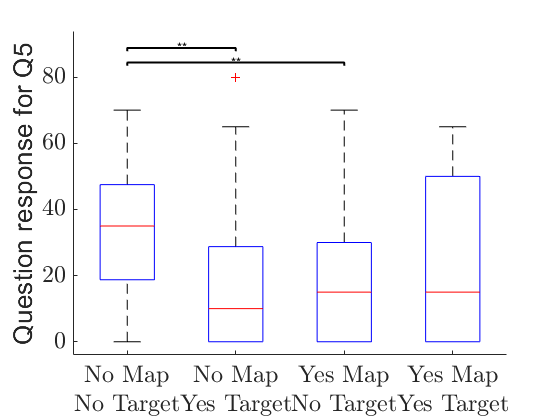

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


NASATLXArrayQ6 = csvread('stats data/TLX_question_6.csv');
t_NASATLXQ6 = array2table(NASATLXArrayQ6,...
    'VariableNames',{'C1','C2','C3','C4'});
NASATLXQ6_bp = boxplot(table2array(t_NASATLXQ6), 'labels', {'C1','C2','C3','C4'});
ylabel('Question response for Q6')
within2=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_NASATLXQ6=fitrm(t_NASATLXQ6,'C1-C4~1', 'WithinDesign', within2);
stats_NASATLXQ6 = ranova(rm_NASATLXQ6)

stats_NASATLXQ6 = 2×8 table
                        SumSq     DF    MeanSq      F        pValue     pValueGG    pValueHF    pValueLB
                        ______    __    ______    ______    ________    ________    ________    ________

    (Intercept):cond    2085.1     3    695.04    2.8855    0.040434    0.059933    0.055036    0.10047 
    Error(cond)          20234    84    240.88                                                          


if stats_NASATLXQ6.pValue(1) < 0.05
    res_NASATLXQ6=multcompare(rm_NASATLXQ6, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_NASATLXQ6,1)
end

res_NASATLXQ6 = 12×7 table
    cond_1    cond_2    Difference    StdErr     pValue       Lower       Upper  
    ______    ______    __________    ______    ________    _________    ________

      1         2          10.69      3.7937    0.052627    -0.080299       21.46
      1         3         5.6897      2.9227     0.36999      -2.6077      13.987
      1         4         1.0345       5.136           1      -13.546      15.615
      2         1         -10.69      3.7937    0.052627       -21.46    0.080299
      2         3             -5      3.2354     0.80088      -14.185      4.1852
      2         4        -9.6552      3.9387     0.12439      -20.837      1.5264
      3         1        -5.6897      2.9227     0.36999      -13.987      2.6

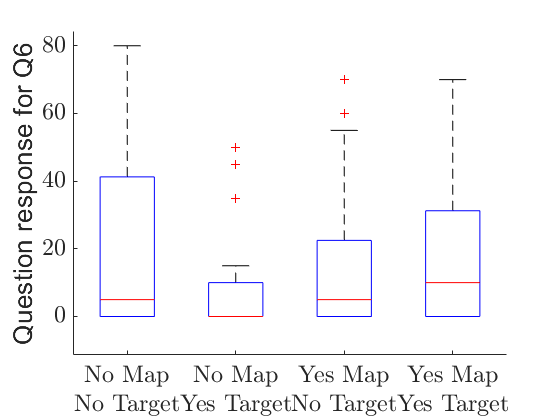

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};


% -- commanded acceleration
ComAccelArray = csvread('stats data/CommandedAccel.csv');
t_ComAccelArray = array2table(ComAccelArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
ComAccelArray_bp = boxplot(table2array(t_ComAccelArray(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Commanded Acceleration (m/s)')
rm_ComAccelArray=fitrm(t_ComAccelArray,'C1-C4~1', 'WithinDesign', within);
stats_ComAccelArray = ranova(rm_ComAccelArray)

stats_ComAccelArray = 2×8 table
                          SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF     pValueLB 
                        _________    __    __________    ______    __________    __________    __________    _________

    (Intercept):cond     0.001777     3    0.00059234    13.017    4.6291e-07    0.00079203    0.00075578    0.0011895
    Error(cond)         0.0038225    84    4.5507e-05                                                                 


if stats_ComAccelArray.pValue(1) < 0.05
    res_ComAccelArray=multcompare(rm_ComAccelArray, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_ComAccelArray,1)
end

res_ComAccelArray = 12×7 table
    cond_1    cond_2    Difference       StdErr       pValue         Lower         Upper   
    ______    ______    ___________    __________    _________    ___________    __________

      1         2        5.1992e-05    0.00042303            1      -0.001149     0.0012529
      1         3         0.0012185    0.00045367     0.072152    -6.9451e-05     0.0025064
      1         4        -0.0085451     0.0024674     0.010408       -0.01555    -0.0015403
      2         1       -5.1992e-05    0.00042303            1     -0.0012529      0.001149
      2         3         0.0011665    0.00055776      0.27412    -0.00041695     0.0027499
      2         4        -0.0085971     0.0025042     0.011252      -0.015706    -0.00

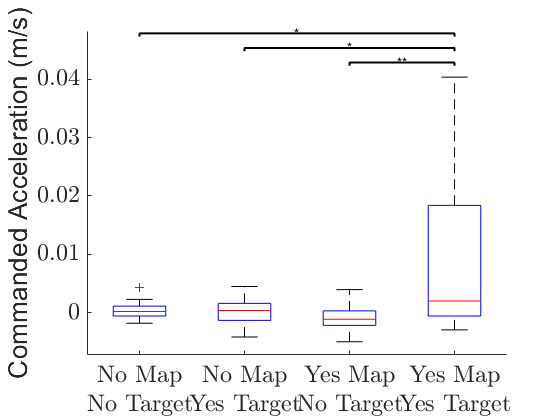

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} No Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} No Map \\ Yes Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Yes Target\end{tabular}'};



% Total time in place traveled
TotalTimeInPlaceArray = csvread('stats data/TotalTimeInPlace.csv');
TotalTimeInPlaceArray(:,1)=TotalTimeInPlaceArray(:,1)/2.27;
TotalTimeInPlaceArray = TotalTimeInPlaceArray((TotalTimeInPlaceArray(:,5) ~= 0), [3,4,5]);
t_TotalTimeInPlace = array2table(TotalTimeInPlaceArray,...
    'VariableNames',{'C1','C2','C3'});
TotalDist_bp = boxplot(table2array(t_TotalTimeInPlace(:,1:3)), 'labels', {'C1','C2','C3'});
ylabel('Fraction time spent turning in place')
rm_TotalTimeInPlace=fitrm(t_TotalTimeInPlace,'C1-C3~1', 'WithinDesign', within3);
stats_TotalTimeInPlace = ranova(rm_TotalTimeInPlace)

stats_TotalTimeInPlace = 2×8 table
                         SumSq      DF     MeanSq        F        pValue       pValueGG      pValueHF      pValueLB 
                        ________    __    _________    ______    _________    __________    __________    __________

    (Intercept):cond     0.25721     2      0.12861    37.262    2.318e-08    9.1396e-07    2.9688e-07    3.7543e-05
    Error(cond)         0.089737    26    0.0034514                                                                 


if stats_TotalTimeInPlace.pValue(1) < 0.05
    res_TotalTimeInPlace=multcompare(rm_TotalTimeInPlace, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_TotalTimeInPlace,1)
end

res_TotalTimeInPlace = 6×7 table
    cond_1    cond_2    Difference     StdErr       pValue        Lower         Upper  
    ______    ______    __________    ________    __________    __________    _________

      1         2         0.18657     0.014996     4.063e-08       0.14539      0.22775
      1         3        0.055156     0.023348       0.10328    -0.0089567      0.11927
      2         1        -0.18657     0.014996     4.063e-08      -0.22775     -0.14539
      2         3        -0.13141      0.02663    0.00081825      -0.20453    -0.058286
      3         1       -0.055156     0.023348       0.10328      -0.11927    0.0089567
      3         2         0.13141      0.02663    0.00081825      0.058286      0.20453


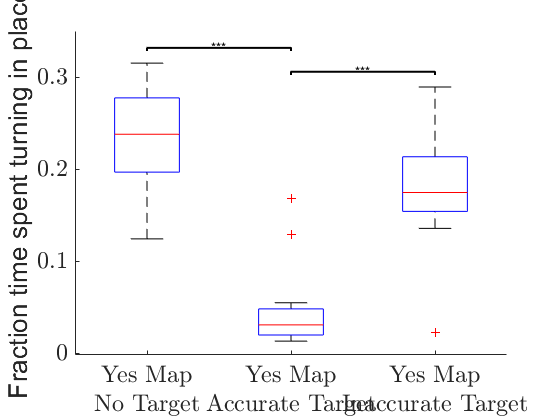

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Accurate Target \end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Inaccurate Target \end{tabular}'};


TotalPercentStoppingArray = csvread('stats data/TotalPercentStopping.csv');
TotalPercentStoppingArray = TotalPercentStoppingArray((TotalPercentStoppingArray(:,5) ~= 0), [3,4,5]);
t_TotalPercentStoppingArray = array2table(TotalPercentStoppingArray,...
    'VariableNames',{'C1','C2','C3'});
Totalpercentstopping_bp = boxplot(table2array(t_TotalPercentStoppingArray(:,1:3)), 'labels', {'C1','C2','C3'});
ylabel('Fraction time spent staying still')
rm_TotalPercentStoppingArray=fitrm(t_TotalPercentStoppingArray,'C1-C3~1', 'WithinDesign', within3);
stats_TotalPercentStoppingArray = ranova(rm_TotalPercentStoppingArray)

stats_TotalPercentStoppingArray = 2×8 table
                         SumSq     DF     MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                        _______    __    ________    ______    __________    __________    __________    __________

    (Intercept):cond    0.55581     2     0.27791    22.016    2.5457e-06    1.8378e-05    6.8663e-06    0.00042117
    Error(cond)          0.3282    26    0.012623                                                                  


if stats_TotalPercentStoppingArray.pValue(1) < 0.05
    res_TotalPercentStoppingArray=multcompare(rm_TotalPercentStoppingArray, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_TotalPercentStoppingArray,1)
end

res_TotalPercentStoppingArray = 6×7 table
    cond_1    cond_2    Difference     StdErr       pValue        Lower         Upper  
    ______    ______    __________    ________    __________    __________    _________

      1         2         0.27751     0.035421    8.4266e-06       0.18025      0.37477
      1         3        0.096418     0.038399       0.07813    -0.0090217      0.20186
      2         1        -0.27751     0.035421    8.4266e-06      -0.37477     -0.18025
      2         3        -0.18109     0.051776      0.011796      -0.32326    -0.038919
      3         1       -0.096418     0.038399       0.07813      -0.20186    0.0090217
      3         2         0.18109     0.051776      0.011796      0.038919      0.32326


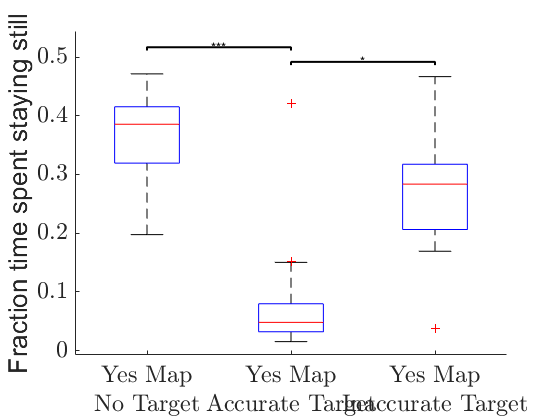

% -- make figure look nice
box off;
ax = gca;
ax.FontSize = 18;
ax.TickLabelInterpreter = 'latex';
ax.XTickLabel = {'\begin{tabular}{c} Yes Map \\ No Target\end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Accurate Target \end{tabular}',...
                 '\begin{tabular}{c} Yes Map \\ Inaccurate Target \end{tabular}'};


% post trial


% we place target in a different location in 4b to see the change in behavior
% when the participant realizes that their prior knowledge is inaccurate
% we compared the actions between condition 3, when they did not have any knowledge
% of target location and condition 4b, when they again don't have knowledge about target location
% but thought they did
% 3 and 4b


% 
% % -- display all tables that contain the data from the input, tracker and
% % -- the questionnaires
% % t_time
% % t_Vel
% % t_EKFSpd
% % t_Omega
% % t_EKFOmega
% % t_TotalTimeInPlace
% % t_TotalTimeStoppingArray
% % t_TotalPercentStoppingArray
% % t_NASATLX
% % t_ComAccelArray
% 
% % -- create box plots for each of the tables, solely looking at conditions 1-4
% % -- all at the same time
% 
% 
% 
% 
% % -- apply the within to the data to get the rm
% % -- for right now solely look at conditions 1-4 without the questions
% 
% 
% % -- display the repeated measures for all data
% rm_time
% rm_Vel
% rm_EKFSpd
% rm_Omega
% rm_EKFOmega
% rm_TotalTimeInPlace
% rm_TotalTimeStoppingArray
% rm_TotalPercentStoppingArray
% rm_NASATLX
% rm_ComAccelArray
% 
% % -- after running the fit rm function, run the stats function and display it
% 
% 
% % -- check if the stats p value is below 0.05, if it is, display the
% % -- pairwise comparisons
% 




% 